# Расчет необходимого количества метана для калибровки

format long g
V_total = 50;           % объем камеры в м³
t = 20;                 % температура в Цельсиях
T = 273 + t;            % температура в Кельвинах
p = 101325;             % давление, Па
R = 8.31446261815324;   % Дж/(моль∙К)

% ppmNu - мольная доля [микромоль/моль]
% ppmW - массовая доля [мг/кг]
% ppmV - объемная доля [см³/м³]

mu_air = 0.02897;       % молярная масса воздуха, кг/моль
mu_CH4 = 0.01604;       % молярная масса метана, кг/моль
nu_air = p * V_total / ( R * T ); % количество воздуха, моль

% Один моль любого газа в количестве числа Авогадро А = 6,022⋅10^23 молекул занимает объём 22414 см³ при нормальных условиях,
% т.е. при атмосферном давлении, равном 1 физической атмосфере (Ра = 760 мм рт. ст.) и при температуре t = 0°С
V_m = R * T/p;          % молярный объем любого газа при заданных условиях в м³

### Расчет массы и молей метана в баллоне по объему и давлению 

V_bottle_liter = 2;                     % объем баллона в литрах
p_bottle_bar = 100;                     % давление в баллоне, бар
p_CH4_bottle = p_bottle_bar * 10^5;     % перевод бар в Паскали
V_CH4_bottle = V_bottle_liter / 1000;   % перевод литров в м³;
m_CH4_bottle = p_CH4_bottle * V_CH4_bottle * mu_CH4 / (R * T); % кг
nu_CH4_bottle = m_CH4_bottle / mu_CH4;
fprintf('Масса метана в баллоне %i л с давлением %i бар = %.3f кг\nКоличество вещества = %.2f моль CH4', V_bottle_liter, p_bottle_bar, m_CH4_bottle, nu_CH4_bottle)

Масса метана в баллоне 2 л с давлением 100 бар = 0.132 кг
Количество вещества = 8.21 моль CH4

### Расчет объёмной/мольной/массовой доли метана в помещении в случае утечки всего газа из баллона

% молярный объем газа в баллоне
V_bottle_m = R * T / p_CH4_bottle;
% какой объем в м³ занимал бы метан из баллона в комнатных условиях
V_withoutbottle_CH4 = V_CH4_bottle * p_CH4_bottle / p;
% объемная доля - безразмерная величина, равная отношению объёма какого-то вещества в смеси к сумме объёмов компонентов до смешивания
frac_CH4_V = V_withoutbottle_CH4 / (V_total + V_withoutbottle_CH4);
ppmV = frac_CH4_V * 10^6; % [см³/м³]
% мольная доля - отношение количества вещества к общему количеству всех веществ, содержащихся в смеси
frac_CH4_nu = nu_CH4_bottle / (nu_CH4_bottle + nu_air);
ppmNu = frac_CH4_nu * 10^6; % [микромоль/моль]
% расчет объемной доли через молярный объем
frac_CH4_Vm = V_m * nu_CH4_bottle / ( V_total + V_withoutbottle_CH4);
% расчет массовой доли
frac_CH4_m = nu_CH4_bottle * mu_CH4 / (nu_CH4_bottle * mu_CH4 + nu_air * mu_air);
ppmW = frac_CH4_m * 10^6; %[мг/кг]
% ppmV == ppmNu

**Метан** становится взрывоопасен при **концентрации** его от 4,4 % до 17 %. Наиболее **взрывоопасная концентрация** в смеси с воздухом 9,5 об. %.

LowExplosionLevel = 0.044; % нижний концентрационный предел распределения пламени, минимальная концентрация горючего взрывоопасного вещества в однородной смеси с окислительной средой, при которой возможен взрыв.
HighExplosionLevel = 0.17; % объемная доля
if frac_CH4_V < LowExplosionLevel || frac_CH4_V > HighExplosionLevel
    fprintf('Содержание метана в процентах по объему\nниже взрывоопасной концентрации в %i раз', round(LowExplosionLevel / frac_CH4_V));
elseif frac_CH4_V > 0.17
    fprintf('Содержание метана в процентах по объему\nвыше взрывоопасной концентрации в %i раз', round( frac_CH4_V / HighExplosionLevel));
else
   disp('Взрывоопасная концентрация!!!') 
end

Содержание метана в процентах по объему
ниже взрывоопасной концентрации в 11 раз

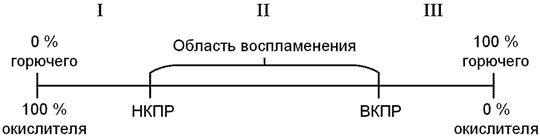

I - область безопасных концентраций; II - область воспламенения; III - область пожароопасных концентраций.

### Расчёт массы и объёма метана для заданного объёма $V_{\mathrm{air}}$ и объемной доли $n$

$\left\lbrace \begin{array}{l}
\frac{\nu_{{\textrm{CH}}_4 } }{\nu_{\textrm{total}} }=\textrm{ppm}\times {10}^{-6} =n\\
\nu_{\textrm{total}} =\nu_{{\textrm{CH}}_4 } +\nu_{\textrm{air}} 
\end{array}\right.$$\Longrightarrow n=\frac{\nu_{{\mathrm{CH}}_4 } }{\nu_{{\mathrm{CH}}_4 } +\nu_{\mathrm{air}} }\Longrightarrow \nu_{{\mathrm{CH}}_4 } =\frac{n\times \nu_{\mathrm{air}} }{1-n}\;$ (уравнения справедливы для объема и для количества вещества)

V_camera_liter = 100 ; % литры
ppmV_CH4 = 1000 ; % ppm
n = ppmV_CH4 * 10^(-6); % доля
V_camera_m3 = V_camera_liter / 1000; % м³
V_CH4 = n * V_camera_m3 / (1 - n);
m_CH4 = V_CH4 * p * mu_CH4 / (R * T);
fprintf("Необходимый объём метана: %.2f мл", V_CH4 * 10^6);

Необходимый объём метана: 100.10 мл

fprintf("Необходимая масса метана: %.2f мг", m_CH4 * 10^6);

Необходимая масса метана: 66.78 мг